clear;
addpath('input')
addpath('function');

%数据读取
filename1='增长因子预测.xlsx';
filename2='通胀因子预测_2024-01-10.xlsx';
filename3='信用因子预测_2024-01-12.xlsx';
filename4='货币因子.xlsx';
zengzhang = readcell(filename1);
tongzhang = readcell(filename2);
xingyong = readcell(filename3);
huobi = readcell(filename4);

%数据预处理和训练、测试集分离。函数参数含义见程序说明
[zengzhang_train,zengzhang_test]=data_preprocessing(zengzhang,'2012-01-07','2023-03-07','2024-01-28','周',[2 11 9 27],[1:4 6:9 11:45 50]);
[tongzhang_train,tongzhang_test]=data_preprocessing(tongzhang,'2012-01-07','2023-03-07','2024-01-28','周',[51 55 59:96],[1:13 16:48 51:96]);
[xingyong_train,xingyong_test]=data_preprocessing(xingyong,'2012-01-07','2023-03-07','2024-01-28','周',[],[1:23 26:41]);

[huobi_train,huobi_test]=data_preprocessing(huobi,'2012-01-07','2023-03-07','2024-01-28','周',[],1:17);

%%%%以下为增长因子的Nowcasting

%扩大代理指标集
zengzhang_train3=combine_data(zengzhang_train,tongzhang_train);
zengzhang_test3=combine_data(zengzhang_test,tongzhang_test);

zengzhang_train2=combine_data(zengzhang_train,xingyong_train);
zengzhang_test2=combine_data(zengzhang_test,xingyong_test);

Res_zengzhang=DFM(zengzhang_train3,4,1,1,'工业增加值:累计同比',1,0);

似然判据为-0.0016，模型不恰当。

Res_zengzhang2=DFM(zengzhang_train2,4,1,1,'制造业PMI',1,0);

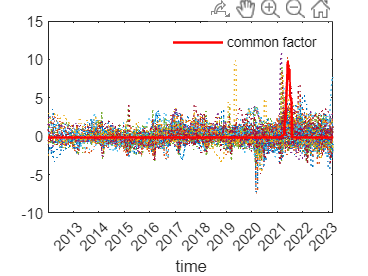

common_factor(Res_zengzhang)

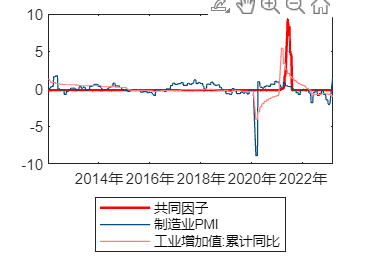

%主要因子与增长指标
notnan=~isnan(Res_zengzhang.y(:,44));
plot(Res_zengzhang.date(notnan),normalize(Res_zengzhang.f(notnan,1)),'color',[1 0 0],'LineWidth',1.5);
hold on
plot(Res_zengzhang.date(notnan),normalize(Res_zengzhang2.y(notnan,75)),'color',[4 78 125]/255,'LineWidth',0.75);
plot(Res_zengzhang.date(notnan),normalize(Res_zengzhang.y(notnan,44)),'color',[255 128 128]/255,'LineWidth',0.75); 
hold off
legend('共同因子','制造业PMI','工业增加值:累计同比', ...
    Location='southoutside')

预测R^2=0.9271

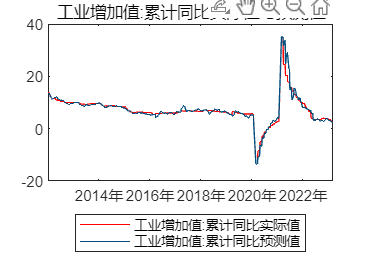

ans = 0.9271

history_fitting(Res_zengzhang,'工业增加值:累计同比')

预测R^2=-0.2985

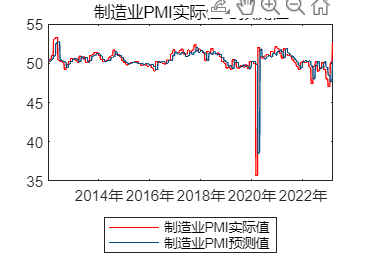

ans = -0.2985

history_fitting(Res_zengzhang2,'制造业PMI')

预测R^2=0.8609

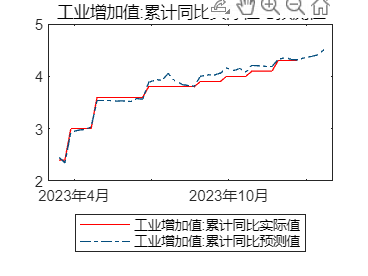

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_zengzhang,zengzhang_test3,'工业增加值:累计同比');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.35);%设置阈值
names_need=Res_zengzhang.Name(select3);%指标名称
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×7 cell 数组
    {'全国二手房出售挂牌价指数'}    {'全国二手房出售挂牌价指数'}    {'义乌小商品价格指数:总指数'}    {'CRB现货指数:工业'}    {'水泥价格指数:全国'}    {'钢材综合价格指数(CSPI):冷轧薄板:1'}    {'钢材综合价格指数(CSPI):高线:Φ6.5'}


weight_need=weight_need'

weight_need =     2.4930    2.4930    0.9690    0.8540    0.5210    0.4150    0.3960


预测R^2=0.8332

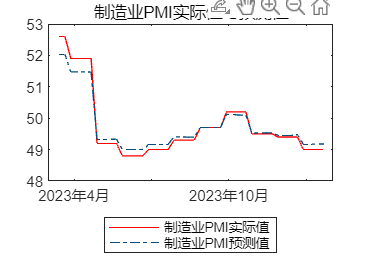

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_zengzhang2,zengzhang_test2,'制造业PMI');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.001);%设置阈值
names_need=Res_zengzhang2.Name(select3);%指标名称
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×7 cell 数组
    {'全国二手房出售挂牌价指数'}    {'义乌小商品价格指数:总指数'}    {'全国二手房出售挂牌价指数（计算变化）'}    {'社会融资规模存量增速:人民币贷款'}    {'沥青:产量(周)'}    {'中国出口集装箱运价指数(CCFI):综合指数（计算变化）'}    {'义乌小商品价格指数:总指数（计算变化）'}


weight_need=weight_need'

weight_need =     0.2350    0.0030    0.0020    0.0020    0.0010    0.0010    0.0010


%%%%%%以下为通胀因子

%月度训练集作为对照
[tongzhang_train2,tongzhang_test2]=data_preprocessing(tongzhang,'2012-01-28','2023-02-28','2024-01-28','月',[51 55 59:96],[1:13 16:48 51:96]);

Res_tongzhang1=DFM(tongzhang_train,3,1,1,'CPI:当月同比',1,0);

Res_tongzhang2=DFM(tongzhang_train2,3,1,1,'CPI:当月同比',1,0);

预测R^2=0.9339

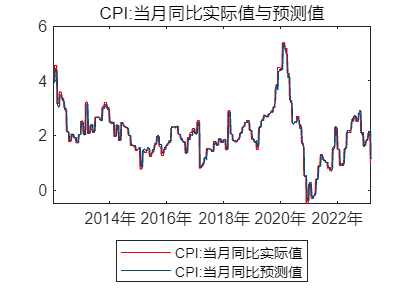

ans = 0.9339

history_fitting(Res_tongzhang1,'CPI:当月同比')

预测R^2=0.8055

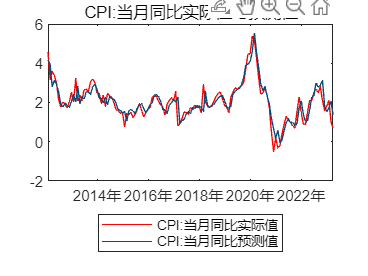

ans = 0.8055

history_fitting(Res_tongzhang2,'CPI:当月同比')

预测R^2=0.8649

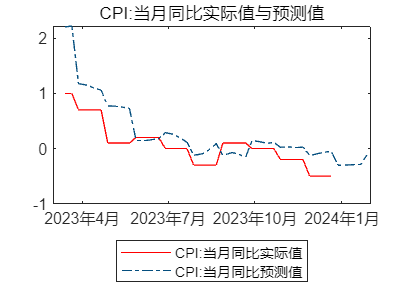

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_tongzhang1,tongzhang_test,'CPI:当月同比');

预测R^2=0.5339

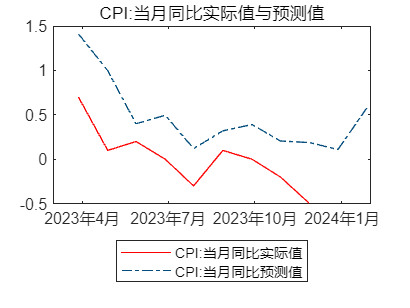

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_tongzhang2,tongzhang_test2,'CPI:当月同比');

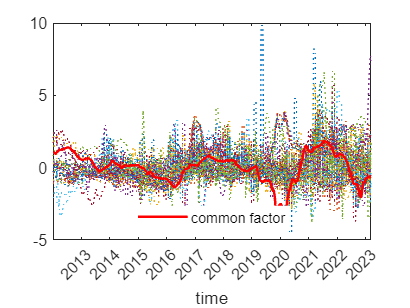

common_factor(Res_tongzhang1)

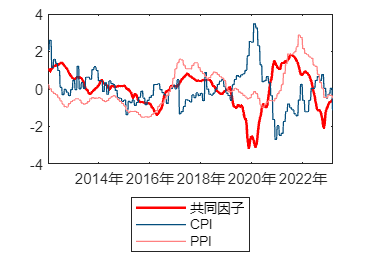

plot(Res_tongzhang1.date,normalize(Res_tongzhang1.f(:,1)),'color',[1 0 0],'LineWidth',1.5);
hold on
plot(Res_tongzhang1.date,normalize(Res_tongzhang1.y(:,11)),'color',[4 78 125]/255,'LineWidth',0.75);
plot(Res_tongzhang1.date,normalize(Res_tongzhang1.y(:,46)),'color',[1 0.5 0.5],'LineWidth',0.75); 
hold off
legend('共同因子','CPI','PPI',Location='southoutside')

预测R^2=0.9741

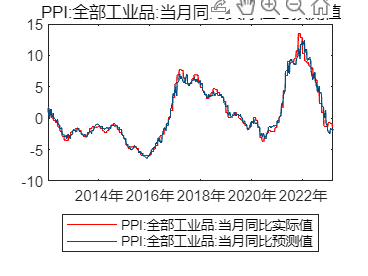

ans = 0.9741

history_fitting(Res_tongzhang1,'PPI:全部工业品:当月同比')

预测R^2=0.7703

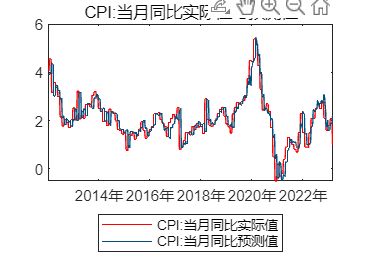

ans = 0.7703

history_fitting(Res_tongzhang1,'CPI:当月同比')

预测R^2=0.8807

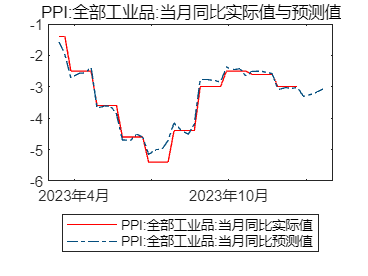

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_tongzhang1,tongzhang_test,'PPI:全部工业品:当月同比');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.8);%设置阈值
names_need=Res_tongzhang1.Name(select3);
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×7 cell 数组
    {'CRB现货指数:综合'}    {'CRB现货指数:工业'}    {'柯桥纺织价格指数'}    {'南华工业品指数'}    {'南华工业品指数'}    {'南华金属指数'}    {'全国二手房出售挂牌价指数'}


weight_need=weight_need'

weight_need =     2.8230    2.4650    2.0120    0.9460    0.9460    0.8240   -1.1060


预测R^2=0.8649

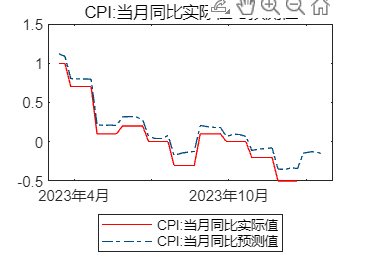

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_tongzhang1,tongzhang_test,'CPI:当月同比');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.15);%设置阈值
names_need=Res_tongzhang1.Name(select3);
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×6 cell 数组
    {'全国大中城市:猪粮比价'}    {'平均批发价:猪肉'}    {'CRB现货指数:综合'}    {'义乌小商品价格指数:总指数'}    {'CRB现货指数:工业'}    {'全国二手房出售挂牌价指数'}


weight_need=weight_need'

weight_need =     0.2440    0.1860   -0.1610   -0.2020   -0.2410   -0.3330


%%%%%以下是信用因子

xingyong_train2=combine_data(xingyong_train,tongzhang_train);
xingyong_test2=combine_data(xingyong_test,tongzhang_test);

Res_xingyong1=DFM(xingyong_train,5,1,1,'社会融资规模增量:累计同比',1,0);

Res_xingyong2=DFM(xingyong_train2,5,1,1,'社会融资规模增量:累计同比',1,0);

似然判据为-0.0206，模型不恰当。

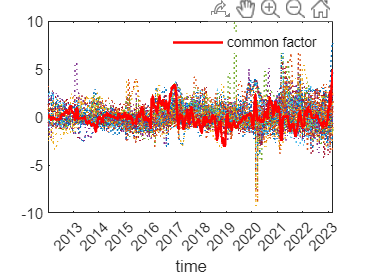

common_factor(Res_xingyong)

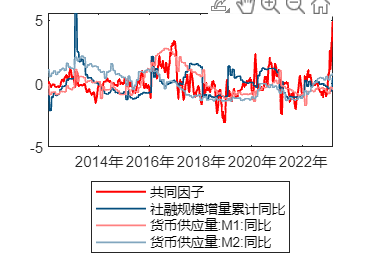

plot(Res_xingyong.date,normalize(Res_xingyong.f(:,1)),'color',[1 0 0],'LineWidth',1.2);
hold on
plot(Res_xingyong.date,normalize(Res_xingyong.y(:,39)),'color',[4 78 125]/255,'LineWidth',1);

plot(Res_xingyong.date,normalize(Res_xingyong.y(:,36)),'color',[255 128 128]/255,'LineWidth',1); 
plot(Res_xingyong.date,normalize(Res_xingyong.y(:,35)),'color',[129 166 190]/255,'LineWidth',1); 
hold off
legend('共同因子','社融规模增量累计同比','货币供应量:M1:同比', ...
    '货币供应量:M2:同比',Location='southoutside')

预测R^2=0.8671

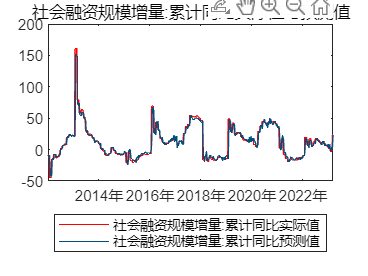

ans = 0.8671

history_fitting(Res_xingyong,'社会融资规模增量:累计同比')

预测R^2=0.9696

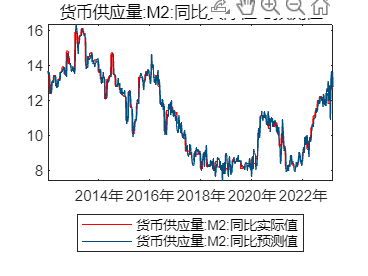

ans = 0.9696

history_fitting(Res_xingyong,'货币供应量:M2:同比')

预测R^2=0.8376

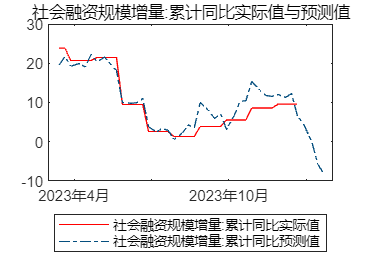

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_xingyong1,xingyong_test,'社会融资规模增量:累计同比');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.01);%设置阈值
names_need=Res_xingyong.Name(select3);
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×5 cell 数组
    {'全国二手房出售挂牌价指数（计算变化）'}    {'22省市:均价:生猪（计算变化）'}    {'社会融资规模存量增速:人民币贷款'}    {'第一财经研究院中国金融条件指数'}    {'大宗商品价格指数BPI（计算变化）（变频）'}


weight_need=weight_need'

weight_need =     0.1660    0.0380    0.0320    0.0230   -0.0260


预测R^2=0.7751

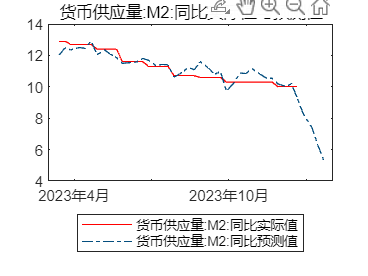

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_xingyong1,xingyong_test,'货币供应量:M2:同比');

%%%%%以下为货币因子
Res_huobi=DFM(huobi_train,1,1,1,'国债到期收益率:1年',1,0);

似然判据为-0.0001，模型不恰当。

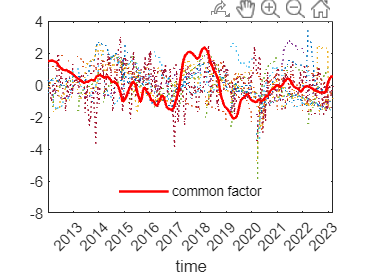

common_factor(Res_huobi)

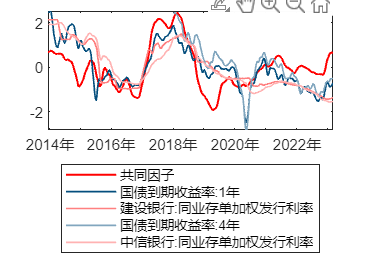

notnan=~(isnan(Res_huobi.y(:,10)));
plot(Res_huobi.date(notnan),normalize(Res_huobi.f(notnan,1)),'color',[1 0 0],'LineWidth',1.2);
hold on
plot(Res_huobi.date(notnan),normalize(Res_huobi.y(notnan,17)),'color',[4 78 125]/255,'LineWidth',1);

plot(Res_huobi.date(notnan),normalize(Res_huobi.y(notnan,10)),'color',[255 128 128]/255,'LineWidth',1); 
plot(Res_huobi.date(notnan),normalize(Res_huobi.y(notnan,16)),'color',[129 166 190]/255,'LineWidth',1); 
plot(Res_huobi.date(notnan),normalize(Res_huobi.y(notnan,13)),'color',[255 178 178]/255,'LineWidth',1);
%plot(Res_huobi.date(notnan),normalize(Res_huobi.y(notnan,1)),'color',[180 202 216]/255,'LineWidth',1);
hold off
legend('共同因子','国债到期收益率:1年','建设银行:同业存单加权发行利率', ...
   '国债到期收益率:4年','中信银行:同业存单加权发行利率',Location='southoutside')

预测R^2=0.9908

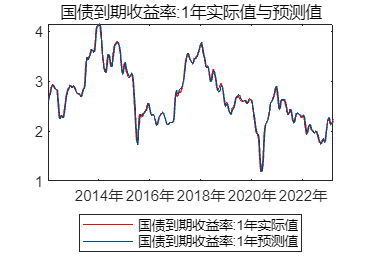

ans = 0.9908

history_fitting(Res_huobi,'国债到期收益率:1年')

预测R^2=0.9980

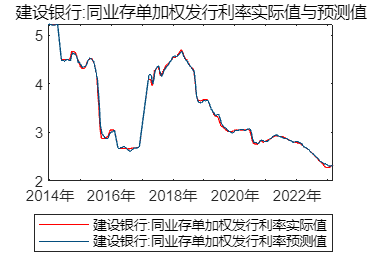

ans = 0.9980

history_fitting(Res_huobi,'建设银行:同业存单加权发行利率')

预测R^2=0.9852

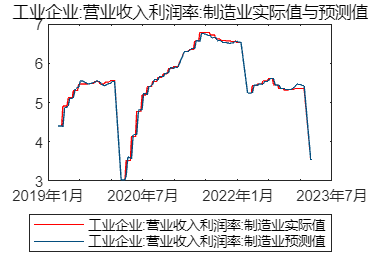

ans = 0.9852

history_fitting(Res_huobi,'工业企业:营业收入利润率:制造业')

预测R^2=0.9509

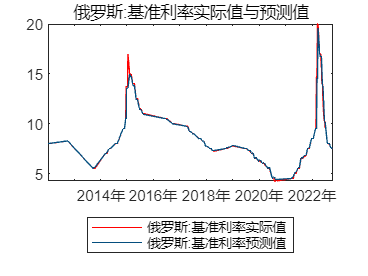

ans = 0.9509

history_fitting(Res_huobi,'俄罗斯:基准利率')

预测R^2=0.9336

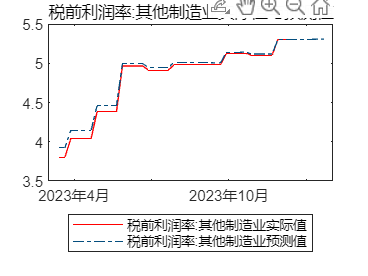

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_huobi,huobi_test,'税前利润率:其他制造业');

预测R^2=0.9613

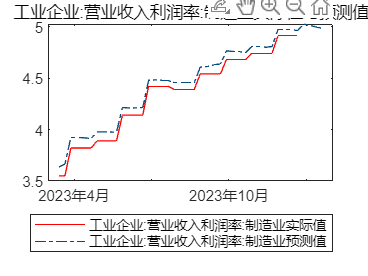

[real,forecasts,adjust,f,weight,e_new]=nowcasting(Res_huobi,huobi_test,'工业企业:营业收入利润率:制造业');

%再跑完一个nowcasting后跑这个代码块获得权重和主要指标
select3=(abs(weight)>0.001);%设置阈值
names_need=Res_xingyong.Name(select3);
[weight_need,index_sort]=sort(round(weight(select3),3),'descend');%对应权重
names_need=names_need(index_sort)

names_need = 1×7 cell 数组
    {'22省市:均价:生猪（计算变化）'}    {'大宗商品价格指数BPI（计算变化）（变频）'}    {'货币供应量:M2:同比'}    {'社会融资规模存量:政府债券（计算变化）'}    {'第一财经研究院中国金融条件指数'}    {'社会融资规模存量增速:人民币贷款'}    {'全国二手房出售挂牌价指数（计算变化）'}


weight_need=weight_need'

weight_need =     0.0070    0.0060    0.0010   -0.0020   -0.0060   -0.0070   -0.0400


function[datanew]=combine_data(data1,data2)
datanew.dates=data1.dates;
datanew.y=[data1.y data2.y];
datanew.names=[data1.names data2.names];
datanew.freqs=[data1.freqs data2.freqs];
end